# **Manhattan Taxi Demand Forecasting**

*Predictive Modeling and Machine Learning with MATLAB*

# 1. Contextualização

Despachantes e motoristas de táxi em Manhattan enfrentam diariamente a mesma pergunta: para onde vale a pena ir agora? Os dados de viagens de táxi amarelo de 2015 permitem responder a essa pergunta de forma sistemática, revelando como a demanda varia entre diferentes regiões e períodos do ano.

A partir desses dados, o projeto desenvolve um pipeline de ciência de dados que transforma registros individuais de viagens em uma visão consolidada da demanda por região e hora. O resultado dessa preparação é uma base com 52.560 observações, representando 6 regiões de interesse ao longo das 8.760 horas de 2015, com a demanda classificada em três níveis: Baixa, Média e Alta.

O objetivo final é fornecer aos despachantes e motoristas uma indicação simples e rápida do nível de demanda esperado em cada região, facilitando a tomada de decisão sem exigir a interpretação de previsões numéricas contínuas.

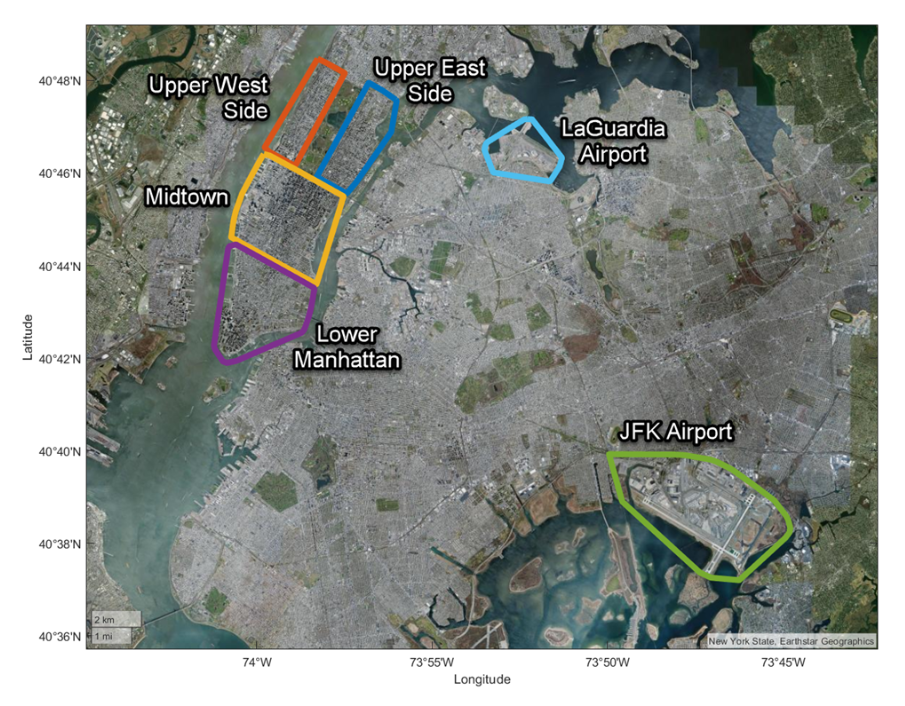

# 2. Cenário

O problema é analisado a partir de duas perspectivas.

**Cenário 1: Modelo baseline.** Busca maximizar a acurácia geral da classificação da demanda. Esse modelo funciona como referência para avaliar diferentes abordagens de modelagem e entender o desempenho preditivo obtido sem priorizar um tipo específico de erro. 

**Cenário 2: Modelo orientado à estratégia de despacho.** Considera que diferentes erros de classificação possuem diferentes impactos para a operação. Nesse cenário, a estratégia de despacho é:

- Priorizar a região de Alta demanda mais próxima quando houver disponibilidade;

- Caso não exista uma região de Alta demanda disponível, direcionar o táxi para a região de Média demanda mais próxima;

- Evitar enviar ou manter táxis em regiões de Baixa demanda. 

Dessa forma, o Cenário 2 atribui maior importância aos erros em que uma região realmente apresenta Baixa demanda, mas é classificada como Média ou Alta. Em contrapartida, aceita-se determinado aumento de classificações como Baixa quando a demanda real é Média ou Alta. Essa priorização é representada por uma matriz de custos que traduz as consequências relativas de cada tipo de erro. 

# 3. Objetivo do Projeto

Desenvolver e comparar modelos capazes de classificar o nível de demanda de táxis por região e hora, avaliando não apenas a capacidade preditiva dos modelos, mas também sua aderência à estratégia operacional de despacho.

O objetivo final é identificar qual abordagem oferece o melhor equilíbrio entre desempenho preditivo e impacto financeiro estimado, apoiando uma decisão de despacho mais alinhada às necessidades do negócio.

Assim, a análise busca responder à seguinte pergunta:

**É mais vantajoso utilizar o modelo com maior acurácia geral ou um modelo que, mesmo apresentando uma pequena redução na acurácia, esteja mais alinhado aos custos dos erros relevantes para a operação?**

**3.1 Arquivos e Dependências do Projeto**

Além dos 12 arquivos mensais de viagens de táxi (yellow_tripdata_2015-*.csv), o projeto depende dos seguintes arquivos e funções auxiliares:

- Taxi Regions and Zones.csv: mapeamento das 260 zonas de táxi da cidade para as 6 regiões de interesse do projeto.

- 2015 Bank Holidays.csv: lista dos feriados bancários de 2015, utilizada na criação do preditor IsHoliday.

- addTaxiZones.mlx: função fornecida no curso que associa cada viagem à sua zona de táxi de embarque e desembarque, a partir de um shapefile geográfico.

- basicPreprocessing.mlx: função fornecida no curso que aplica a limpeza-base dos dados (remoção de valores inconsistentes, negativos e atípicos).

# 4. Desenvolvimento

## **Módulo 01: **Importar e explorar os dados

Neste módulo, os dados brutos de viagens de táxi amarelo de 2015 são importados, organizados, limpos e explorados para compreender sua estrutura e identificar informações relevantes para o problema de negócio. A análise passa pela preparação dos registros de viagens, identificação das regiões de interesse e agregação dos dados por região e hora, resultando em uma visão consolidada da operação. 

Além da preparação dos dados, são realizadas análises exploratórias para compreender características das viagens e identificar possíveis inconsistências ou valores atípicos que possam afetar as etapas seguintes. Ao final deste módulo, os dados estarão estruturados e preparados para a criação da variável de demanda e para as análises realizadas no Módulo 02.

### 1. **Pré-processamento do conjunto de dados**

Este módulo cobre a importação dos doze arquivos mensais de viagens de táxi, a atribuição de zonas e regiões geográficas para cada viagem, e a limpeza dos dados brutos, resultando na tabela agregada por região e hora que serve como base para o restante do projeto.

Os dados brutos são importados usando um `fileDatastore`, combinando os doze arquivos mensais em uma única tabela. Cada viagem recebe sua zona de táxi utilizando a função `addTaxiZones` fornecida no curso, e sua região de embarque (*pickup*) e desembarque (*dropoff*), obtidas ao desconstruir (*unpivoting*) o arquivo de mapeamento de zona para região e relacioná-lo com a zona de cada viagem.

#### ETAPA 1: Configuração do Datastore e Importação dos Dados de Táxi

caminhoPasta = fullfile('Predictive Modeling and Machine Learning', 'Taxi Data');
padraoArquivos = fullfile(caminhoPasta, 'yellow*.csv');

% fileDatastore com a função de importação do Curso 3 como ReadFcn.
% UniformRead=true concatena verticalmente as 12 tabelas mensais automaticamente.
TaxiDatastore = fileDatastore(padraoArquivos, ...
    'ReadFcn', @importTaxiDataWithoutCleaning, ...
    'UniformRead', true);

TaxiAll = readall(TaxiDatastore);


#### ETAPA 2: Adicionar PickupZone e DropoffZone (e boroughs)

A função addTaxiZones, fornecida no curso, associa cada viagem à zona de táxi correspondente ao seu ponto de embarque e desembarque. Ela utiliza um shapefile geográfico (TaxiZones.shp) contendo os limites das 260 zonas oficiais da cidade e verifica, para cada viagem, em qual zona as coordenadas de latitude e longitude estão localizadas. Como resultado, a função adiciona quatro novas variáveis à tabela: PickupZone, DropoffZone e os respectivos boroughs (distritos) de embarque e desembarque. Essa etapa é o que permite, na sequência, mapear cada zona a uma das 6 regiões de interesse do projeto.

% Requer TaxiZones.shp no path do MATLAB (padrão) ou informe o caminho:
% TaxiAll = addTaxiZones(TaxiAll, 'caminho/para/TaxiZones.shp');
TaxiAll = addTaxiZones(TaxiAll);

#### ETAPA 3: Mapear Zonas -> Regiões de táxi (6 regiões)

caminhoRegioes = fullfile('Predictive Modeling and Machine Learning', ...
    'Taxi-Regions-and-Holiday-Files', 'Taxi Regions and Zones.csv');

% 'VariableNamingRule','preserve' mantém os nomes originais com espaço
% (ex: "Lower Manhattan"), que usaremos como nome da região.
regionsTable = readtable(caminhoRegioes, ...
    'VariableNamingRule', 'preserve', 'TextType', 'string');

regionNames = string(regionsTable.Properties.VariableNames);

% "Despivotar": empilha todas as colunas em duas listas paralelas: Zona / Região
zoneList   = strings(0,1);
regionList = strings(0,1);

for i = 1:width(regionsTable)
    col = regionsTable{:,i};
    col = col(col ~= "" & ~ismissing(col));  % remove células vazias
    zoneList   = [zoneList;   col];
    regionList = [regionList; repmat(regionNames(i), numel(col), 1)];
end

zoneToRegion = table(categorical(zoneList), categorical(regionList), ...
    'VariableNames', {'Zone','Region'});

% Adiciona PickupRegion via lookup em PickupZone
[tf, idx] = ismember(TaxiAll.PickupZone, zoneToRegion.Zone);
TaxiAll.PickupRegion = categorical(nan(height(TaxiAll),1));
TaxiAll.PickupRegion(tf) = zoneToRegion.Region(idx(tf));

% Adiciona DropoffRegion via lookup em DropoffZone
[tf, idx] = ismember(TaxiAll.DropoffZone, zoneToRegion.Zone);
TaxiAll.DropoffRegion = categorical(nan(height(TaxiAll),1));
TaxiAll.DropoffRegion(tf) = zoneToRegion.Region(idx(tf));

As verificações a seguir confirmam que as etapas de importação do datastore, atribuição de zonas e mapeamento de regiões produziram o resultado esperado.

#### 1. Visão geral da tabela

size(TaxiAll)          % número de linhas (viagens) x colunas (variáveis)

ans =      2922266          25


TaxiAll.Properties.VariableNames   % conferir se PickupZone, DropoffZone,

ans = 1×25 cell array
    {'Vendor'}    {'PickupTime'}    {'DropoffTime'}    {'Passengers'}    {'Distance'}    {'PickupLon'}    {'PickupLat'}    {'RateCode'}    {'HeldFlag'}    {'DropoffLon'}    {'DropoffLat'}    {'PayType'}    {'Fare'}    {'ExtraCharge'}    {'Tax'}    {'Tip'}    {'Tolls'}    {'ImpSurcharge'}    {'TotalCharge'}    {'tzPickupBorough'}    {'tzDropoffBorough'}    {'PickupZone'}    {'DropoffZone'}    {'PickupRegion'}    {'DropoffRegion'}


% PickupRegion, DropoffRegion existem
head(TaxiAll, 10)       % primeiras 10 linhas, para inspeção visual rápida

    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    tzPickupBorough    tzDropoffBorough             PickupZone                       DropoffZone              PickupRegion       DropoffRegion 
    ______    ___________________    ___________________    __________    ________    

#### 2. Conferir se addTaxiZones funcionou (Etapa 2)

summary(TaxiAll.PickupZone)     % contagem de viagens por zona (260 zonas possíveis)


2922266×1 categorical

     Allerton/Pelham Gardens                               13 
     Alphabet City                                       9363 
     Arden Heights                                          0 
     Arrochar/Fort Wadsworth                                2 
     Astoria                                             6167 
     Astoria Park                                          49 
     Auburndale                                             9 
     Baisley Park                                         414 
     Bath Beach                                            18 
     Battery Park                                        1131 
     Battery Park City                                  26156 
     Bay Ridge                                            133 
     Bay

summary(TaxiAll.DropoffZone)


2922266×1 categorical

     Allerton/Pelham Gardens                              170 
     Alphabet City                                      14955 
     Arden Heights                                         16 
     Arrochar/Fort Wadsworth                               63 
     Astoria                                            15209 
     Astoria Park                                          77 
     Auburndale                                           176 
     Baisley Park                                         837 
     Bath Beach                                           249 
     Battery Park                                        2081 
     Battery Park City                                  28694 
     Bay Ridge                                           2546 
     Bay

% Quantas viagens ficaram sem zona definida?
sum(isundefined(TaxiAll.PickupZone))

ans = 48799

sum(isundefined(TaxiAll.DropoffZone))

ans = 51915

#### 3. Conferir o mapeamento Zona -> Região (Etapa 3)

summary(TaxiAll.PickupRegion)   % deve mostrar só as 6 categorias + <undefined>


2922266×1 categorical

     JFK Airport              62178 
     LaGuardia Airport        70720 
     Lower Manhattan         580591 
     Midtown                1296074 
     Upper East Side         422235 
     Upper West Side         265523 
     <undefined>             224945 


summary(TaxiAll.DropoffRegion)


2922266×1 categorical

     JFK Airport              25608 
     LaGuardia Airport        35891 
     Lower Manhattan         524772 
     Midtown                1205864 
     Upper East Side         421602 
     Upper West Side         249292 
     <undefined>             459237 


% Proporção de viagens que caíram em alguma das 6 regiões
sum(~isundefined(TaxiAll.PickupRegion)) / height(TaxiAll)

ans = 0.9230

sum(~isundefined(TaxiAll.DropoffRegion)) / height(TaxiAll)

ans = 0.8428

Com as regiões de embarque e desembarque definidas, as perguntas a seguir fornecem uma exploração inicial dos dados brutos.

#### Pergunta 1: Tarifa média para viagens com PickupRegion = Lower Manhattan

lowerManhattanTrips = TaxiAll(TaxiAll.PickupRegion == "Lower Manhattan", :);
mediaTarifaLM = mean(lowerManhattanTrips.Fare, 'omitnan');
fprintf('Tarifa média (Lower Manhattan): $%.2f\n', mediaTarifaLM);

Tarifa média (Lower Manhattan): $13.24


#### Pergunta 2: Qual região de coleta tem a MAIOR distância média de viagem?

distanciaMediaPorRegiao = groupsummary(TaxiAll, 'PickupRegion', 'mean', 'Distance');
disp(distanciaMediaPorRegiao)

      PickupRegion       GroupCount    mean_Distance
    _________________    __________    _____________

    JFK Airport               62178       15.919    
    LaGuardia Airport         70720       9.7385    
    Lower Manhattan      5.8059e+05       2.8519    
    Midtown              1.2961e+06       14.732    
    Upper East Side      4.2224e+05        2.212    
    Upper West Side      2.6552e+05       38.474    
    <undefined>          2.2494e+05       71.224    



% Remove a linha <undefined> (viagens fora das 6 regiões) antes de comparar
distanciaMediaPorRegiao = distanciaMediaPorRegiao(~isundefined(distanciaMediaPorRegiao.PickupRegion), :);

[maiorDist, idx] = max(distanciaMediaPorRegiao.mean_Distance);
fprintf('Região com maior distância média: %s (%.2f milhas)\n', ...
    string(distanciaMediaPorRegiao.PickupRegion(idx)), maiorDist);

Região com maior distância média: Upper West Side (38.47 milhas)


#### Pergunta 3: % de viagens com PickupZone dentro de uma das 6 regiões de foco

pctDentroRegioes = sum(~isundefined(TaxiAll.PickupRegion)) / height(TaxiAll) * 100;
fprintf('Percentual de viagens com pickup nas 6 regiões: %.2f%%\n', pctDentroRegioes)

Percentual de viagens com pickup nas 6 regiões: 92.30%


### 2.**Explorar e preparar os dados**

Antes de consolidar o pipeline final de limpeza, é útil medir isoladamente o impacto da rotina baseline fornecida no curso, aplicada diretamente sobre os dados ainda sem os filtros customizados. Esse resultado preliminar serve apenas de referência e será substituído pelo funil de limpeza completo mais adiante.

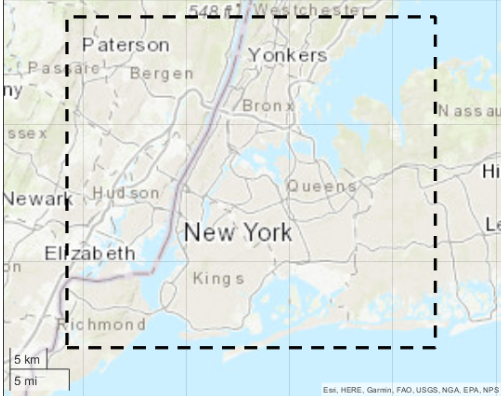

%% Aplicar limpeza baseline 
nLinhasAntes = height(TaxiAll);

TaxiClean = basicPreprocessing(TaxiAll);

nLinhasDepois = height(TaxiClean);
pctRemovido = (nLinhasAntes - nLinhasDepois) / nLinhasAntes * 100;

fprintf('Linhas antes: %d\n', nLinhasAntes);

Linhas antes: 2922266


fprintf('Linhas depois: %d\n', nLinhasDepois);

Linhas depois: 2823701


fprintf('Percentual removido: %.2f%%\n', pctRemovido);

Percentual removido: 3.37%


Como melhoria em relação à limpeza-base fornecida no curso, aplica-se um filtro adicional de tarifa mínima. Em 2015, a bandeirada (tarifa inicial) mínima cobrada por uma corrida de táxi em Nova York era de US$ 2,50. Viagens com tarifa abaixo desse valor são, portanto, fisicamente impossíveis e indicam erro de registro nos dados brutos. Esses erros não são capturados pela rotina baseline, que exige apenas tarifa maior que zero.

%% Melhoria 1: aplicar tarifa mínima realista de $2.50 (bandeirada de 2015)
% Aplicado sobre TaxiAll (dados brutos), antes do basicPreprocessing
nAntesTarifa = height(TaxiAll);
TaxiAll = TaxiAll(TaxiAll.Fare >= 2.50, :);
nDepoisTarifa = height(TaxiAll);

fprintf('Viagens removidas por tarifa < $2.50: %d (%.2f%%)\n', ...
    nAntesTarifa - nDepoisTarifa, (nAntesTarifa - nDepoisTarifa)/nAntesTarifa*100);

Viagens removidas por tarifa < $2.50: 2441 (0.08%)


A razão entre tarifa e distância é investigada para identificar prováveis erros de geolocalização sem remover viagens legítimas, como tarifas fixas para o aeroporto.

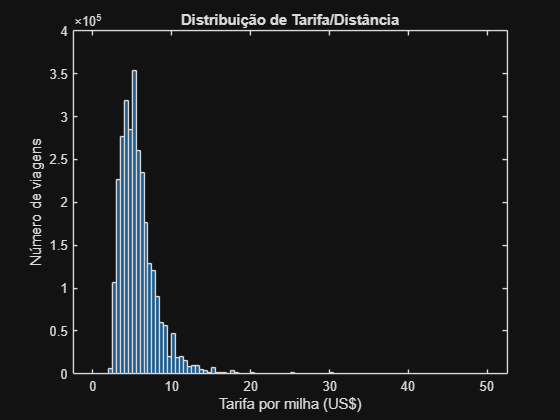

%% Explorar a razão Tarifa/Distância
TaxiAll.FarePerMile = TaxiAll.Fare ./ TaxiAll.Distance;

% Histograma para ver a distribuição (ajuste os limites de eixo conforme necessário)
figure
histogram(TaxiAll.FarePerMile, 'BinLimits', [0 50], 'NumBins', 100)
xlabel('Tarifa por milha (US$)')
ylabel('Número de viagens')
title('Distribuição de Tarifa/Distância')

% Estatísticas para embasar a decisão de corte
prctile(TaxiAll.FarePerMile, [50 90 95 99 99.9])

ans =     5.3125    8.7500   10.5556   23.3333       Inf


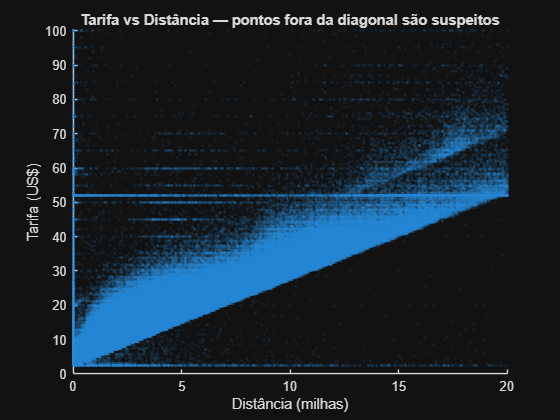

%% Scatter para visualizar tarifa vs distância diretamente
figure
scatter(TaxiAll.Distance, TaxiAll.Fare, 5, 'filled', 'MarkerFaceAlpha', 0.1)
xlabel('Distância (milhas)')
ylabel('Tarifa (US$)')
title('Tarifa vs Distância: pontos fora da diagonal são suspeitos')
xlim([0 20])
ylim([0 100])

%% Aplicar corte de Tarifa/Distância (baseado no 99º percentil ≈ $23.33)
limiarFarePerMile = 25;

% Só marca como suspeito quem tem Distance > 0 (Distance == 0 já será
% removido depois pelo basicPreprocessing, não precisa duplicar aqui)
excluirPorTarifaDistancia = TaxiAll.Distance > 0 & TaxiAll.FarePerMile > limiarFarePerMile;

fprintf('Viagens removidas por Tarifa/Distância > $%d/milha: %d (%.2f%%)\n', ...
    limiarFarePerMile, sum(excluirPorTarifaDistancia), ...
    sum(excluirPorTarifaDistancia)/height(TaxiAll)*100);

Viagens removidas por Tarifa/Distância > $25/milha: 9756 (0.33%)


TaxiAll = TaxiAll(~excluirPorTarifaDistancia, :);

A limpeza combina uma etapa personalizada (tarifa mínima e razão entre tarifa e distância) com a rotina de limpeza baseline fornecida no curso. O funil de limpeza removeu 3,18% das viagens na etapa baseline, aplicada sobre um conjunto de dados já filtrado pelos critérios personalizados, passando de 2.910.069 para 2.817.585 viagens. Os dados são então agregados por região e hora, formando a tabela TaxiSummary com 52.560 linhas (seis regiões multiplicadas por 8.760 horas)

%% Pipeline completo de limpeza (nesta ordem)
nInicial = height(TaxiAll);

% 1. Tarifa mínima realista ($2.50 - bandeirada de 2015)
TaxiAll = TaxiAll(TaxiAll.Fare >= 2.50, :);

% 2. Tarifa/Distância suspeita (feito acima)
TaxiAll.FarePerMile = TaxiAll.Fare ./ TaxiAll.Distance;
excluirPorTarifaDistancia = TaxiAll.Distance > 0 & TaxiAll.FarePerMile > 25;
TaxiAll = TaxiAll(~excluirPorTarifaDistancia, :);
TaxiAll = removevars(TaxiAll, 'FarePerMile'); % coluna auxiliar, não precisa mais

% 3. Limpeza baseline (fornecida no Curso 3)
TaxiClean = basicPreprocessing(TaxiAll);

nFinal = height(TaxiClean);
fprintf('Total inicial: %d\n', nInicial);

Total inicial: 2910069


fprintf('Total final: %d\n', nFinal);

Total final: 2817585


fprintf('Percentual total removido: %.2f%%\n', (nInicial-nFinal)/nInicial*100);

Percentual total removido: 3.18%


A reestruturação agrega a tabela de viagens individuais em uma tabela por região e hora, incluindo combinações sem viagens registradas, que são preenchidas com zero em vez de serem removidas.

%% Preparar variáveis de hora (arredondar timestamps para o início da hora)
TaxiClean.PickupHour  = dateshift(TaxiClean.PickupTime, 'start', 'hour');
TaxiClean.DropoffHour = dateshift(TaxiClean.DropoffTime, 'start', 'hour');

%% Filtrar apenas as 6 regiões de foco (remove <undefined> / "Other")
pickupTrips  = TaxiClean(~isundefined(TaxiClean.PickupRegion), :);
dropoffTrips = TaxiClean(~isundefined(TaxiClean.DropoffRegion), :);

%% Agrupar embarques: contagem + médias de Distância/Duração/Tarifa
pickupSummary = groupsummary(pickupTrips, {'PickupRegion','PickupHour'}, ...
    'mean', {'Distance','Duration','Fare'});

pickupSummary = renamevars(pickupSummary, ...
    {'PickupRegion','PickupHour','GroupCount','mean_Distance','mean_Duration','mean_Fare'}, ...
    {'Region','Hour','Pickups','AvgDistance','AvgDuration','AvgFare'});

%% Agrupar desembarques: apenas contagem
dropoffSummary = groupsummary(dropoffTrips, {'DropoffRegion','DropoffHour'});

dropoffSummary = renamevars(dropoffSummary, ...
    {'DropoffRegion','DropoffHour','GroupCount'}, ...
    {'Region','Hour','Dropoffs'});

%% Criar grade completa: 6 regiões x todas as horas de 2015
regionList = categorical({'Lower Manhattan','Midtown','Upper East Side', ...
    'Upper West Side','JFK Airport','LaGuardia Airport'});

hourList = (datetime(2015,1,1,0,0,0) : hours(1) : datetime(2015,12,31,23,0,0))';

nRegions = numel(regionList);
nHours   = numel(hourList);

fullGrid = table( ...
    repelem(regionList(:), nHours), ...
    repmat(hourList, nRegions, 1), ...
    'VariableNames', {'Region','Hour'});

%% Juntar tudo (left join a partir da grade completa)
TaxiSummary = outerjoin(fullGrid, pickupSummary, ...
    'Keys', {'Region','Hour'}, 'MergeKeys', true, 'Type', 'left');

TaxiSummary = outerjoin(TaxiSummary, dropoffSummary, ...
    'Keys', {'Region','Hour'}, 'MergeKeys', true, 'Type', 'left');

%% Tratar valores ausentes: Pickups/Dropoffs = 0 real (não NaN)
TaxiSummary.Pickups(isnan(TaxiSummary.Pickups))   = 0;
TaxiSummary.Dropoffs(isnan(TaxiSummary.Dropoffs)) = 0;

%% Calcular coletas líquidas
TaxiSummary.NetPickups = TaxiSummary.Pickups - TaxiSummary.Dropoffs;

%% Conferir resultado
size(TaxiSummary)

ans =        52560           8


As verificações a seguir confirmam a estrutura e a integridade da tabela agregada.

head(TaxiSummary, 10)

      Region               Hour            Pickups    AvgDistance    AvgDuration    AvgFare    Dropoffs    NetPickups
    ___________    ____________________    _______    ___________    ___________    _______    ________    __________

    JFK Airport    01-Jan-2015 00:00:00       2          11.71         22.525        33.75        0             2    
    JFK Airport    01-Jan-2015 01:00:00       2          18.25         27.183        47.25        0             2    
    JFK Airport    01-Jan-2015 02:00:00       0            NaN            NaN          NaN        0             0    
    JFK Airport    01-Jan-2015 03:00:00       0            NaN            NaN          NaN        0             0    
    JFK Airport    

summary(TaxiSummary)


TaxiSummary: 52560×8 table

Variables:

    Region: categorical (6 categories)
    Hour: datetime
    Pickups: double
    AvgDistance: double
    AvgDuration: double
    AvgFare: double
    Dropoffs: double
    NetPickups: double

Statistics for applicable variables:

                   NumMissing          Min                   Median                       Max                         Me

% Deve dar 6 regiões x 8760 horas = 52.560 linhas
height(TaxiSummary) == 6*8760

ans = logical
   1


% Quantas combinações região-hora têm zero embarques?
sum(TaxiSummary.Pickups == 0)

ans = 2861

% Testar o exemplo do próprio enunciado:

% duração média em Midtown, 15/fev, 6h-7h
teste = TaxiSummary(TaxiSummary.Region == "Midtown" & ...
    TaxiSummary.Hour == datetime(2015,2,15,6,0,0), :);
disp(teste)

    Region             Hour            Pickups    AvgDistance    AvgDuration    AvgFare    Dropoffs    NetPickups
    _______    ____________________    _______    ___________    ___________    _______    ________    __________

    Midtown    15-Feb-2015 06:00:00      32         3.1259          9.063       11.438        24           8     



resultado2 = TaxiSummary(TaxiSummary.Region == "Midtown" & ...
    TaxiSummary.Hour == datetime(2015,1,17,2,0,0), :);
disp(resultado2)

    Region             Hour            Pickups    AvgDistance    AvgDuration    AvgFare    Dropoffs    NetPickups
    _______    ____________________    _______    ___________    ___________    _______    ________    __________

    Midtown    17-Jan-2015 02:00:00      122        3.0061         10.828       11.549       125           -3    



Análises exploratórias adicionais na tabela agregada observam a tarifa por região e hora, a dispersão dos embarques líquidos e a correlação entre a distância média e a duração média.

%% Pivoteia a tabela: uma coluna de AvgFare para cada região
fareWide = unstack(TaxiSummary(:, {'Region','Hour','AvgFare'}), 'AvgFare', 'Region');

regionNames = fareWide.Properties.VariableNames(2:end);
fareMat = fareWide{:, 2:end};

vencedor = strings(height(fareWide), 1);
for i = 1:height(fareWide)
    linha = fareMat(i, :);
    if all(isnan(linha))
        vencedor(i) = "";   % hora sem nenhuma tarifa válida em nenhuma região
    else
        [~, idx] = max(linha);
        vencedor(i) = regionNames{idx};
    end
end

vencedor = vencedor(vencedor ~= "");   % remove horas sem vencedor definido

% Contagem de vitórias por região
summary(categorical(vencedor))


8757×1 categorical

     JFKAirport            7791 
     LaGuardiaAirport       220 
     LowerManhattan         248 
     Midtown                146 
     UpperEastSide          145 
     UpperWestSide          207 
     <undefined>              0 


regioes = categories(TaxiSummary.Region);
iqrPorRegiao = zeros(numel(regioes), 1);

for i = 1:numel(regioes)
    valores = TaxiSummary.NetPickups(TaxiSummary.Region == regioes{i});
    iqrPorRegiao(i) = iqr(valores);
end

tabelaIQR = table(regioes, iqrPorRegiao, 'VariableNames', {'Region','IQR_NetPickups'});
tabelaIQR = sortrows(tabelaIQR, 'IQR_NetPickups', 'descend');
disp(tabelaIQR)

           Region            IQR_NetPickups
    _____________________    ______________

    {'Midtown'          }          25      
    {'Upper East Side'  }          17      
    {'Lower Manhattan'  }          15      
    {'Upper West Side'  }          12      
    {'LaGuardia Airport'}          10      
    {'JFK Airport'      }           6      



regioes = categories(TaxiSummary.Region);
correlacaoPorRegiao = nan(numel(regioes), 1);

for i = 1:numel(regioes)
    idx = TaxiSummary.Region == regioes{i} & ...
        ~isnan(TaxiSummary.AvgDistance) & ...
        ~isnan(TaxiSummary.AvgDuration);
    correlacaoPorRegiao(i) = corr(TaxiSummary.AvgDistance(idx), TaxiSummary.AvgDuration(idx));
end

tabelaCorr = table(regioes, correlacaoPorRegiao, 'VariableNames', {'Region','Correlation'});
tabelaCorr = sortrows(tabelaCorr, 'Correlation', 'ascend');
disp(tabelaCorr)

           Region            Correlation
    _____________________    ___________

    {'Midtown'          }     -0.10991  
    {'Lower Manhattan'  }     0.039036  
    {'Upper East Side'  }       0.2266  
    {'JFK Airport'      }      0.44327  
    {'Upper West Side'  }      0.50034  
    {'LaGuardia Airport'}      0.52093  



## **Módulo 02**: Criar e avaliar recursos

Neste módulo, os dados preparados anteriormente são utilizados para construir a variável de resposta **Demanda**, classificando cada observação em três níveis: **Baixa, Média ou Alta**. Em seguida, são desenvolvidos recursos relacionados ao período e ao calendário, como região, hora do dia, dia da semana, mês, final de semana e feriado, buscando representar os principais fatores disponíveis para explicar as variações da demanda. 

Também são realizadas análises estatísticas e de associação entre as variáveis para avaliar sua relevância e selecionar o conjunto de recursos que será utilizado na modelagem. Essa etapa é importante para garantir que o modelo do **Módulo 03** seja construído a partir de informações relevantes para o problema, evitando variáveis que possam introduzir circularidade ou informações inadequadas. 

###  1. Criar uma variável de resposta: Demanda por táxis

Com a tabela agregada pronta, este módulo cria a variável de resposta categórica Demand (Baixa, Média, Alta) e desenvolve o conjunto de preditores utilizados na modelagem, avaliando cada um estatisticamente antes de finalizar a lista.

A divisão entre treino e teste é realizada cronologicamente em vez de aleatoriamente, para evitar o vazamento de informações temporais. A variável Demand é então derivada de NetPickups utilizando os limiares de negócio fornecidos.

#### Tarefa 1: Divisão treino/teste (cronológica, para evitar vazamento temporal)

Nesta etapa, os dados são divididos em conjuntos de **treino e teste seguindo a ordem temporal**, garantindo que o modelo aprenda apenas com informações passadas e seja avaliado em dados futuros. Essa separação é fundamental para **evitar vazamento temporal**, que poderia gerar resultados irreais. Assim, o desempenho obtido reflete melhor a capacidade do modelo de **prever situações novas** com base em padrões históricos.

% Ordena por Hora para garantir a divisão cronológica correta
TaxiSummary = sortrows(TaxiSummary, 'Hour');

% Define o corte: por exemplo, 80% do ano para treino, 20% para teste
dataCorte = datetime(2015,11,1,0,0,0);  % Nov e Dez -> teste; Jan-Out -> treino

isTrain = TaxiSummary.Hour < dataCorte;
isTest  = ~isTrain;

TaxiTrain = TaxiSummary(isTrain, :);
TaxiTest  = TaxiSummary(isTest, :);

fprintf('Treino: %d linhas (%.1f%%)\n', height(TaxiTrain), height(TaxiTrain)/height(TaxiSummary)*100);

Treino: 43776 linhas (83.3%)


fprintf('Teste:  %d linhas (%.1f%%)\n', height(TaxiTest), height(TaxiTest)/height(TaxiSummary)*100);

Teste:  8784 linhas (16.7%)


#### Tarefa 2: Criar variável categórica "Demanda"

Esta variável foi criada para representar o nível de movimentação de táxis em diferentes períodos, a partir do número líquido de embarques (*NetPickups*). A metodologia utilizada define três faixas de classificação: valores menores que 0 indicam **baixa demanda**, entre 0 e 15 correspondem a **demanda média**, e acima de 15 representam **alta demanda**.

Essa transformação converte um valor numérico contínuo em uma variável **categórica ordinal**, o que facilita a análise e o treinamento de modelos de aprendizado de máquina. Além de tornar os resultados mais intuitivos, essa abordagem ajuda a identificar padrões de comportamento ao longo do tempo, permitindo compreender melhor os períodos de maior ou menor atividade de táxis na cidade.

% Função auxiliar para não repetir a lógica em Train e Test
function demanda = classificarDemanda(netPickups)
demanda = strings(size(netPickups));
demanda(netPickups < 0)                        = "Baixo";
demanda(netPickups >= 0 & netPickups < 15)      = "Médio";
demanda(netPickups >= 15)                       = "Alto";


43776×1 ordinal categorical

     Baixo            13913 
     Médio            23022 
     Alto              6841 
     <undefined>          0 

Additional statistics:

    Min         Baixo  
    Median      Médio  
    Max         Alto   



demanda = categorical(demanda, {'Baixo','Médio','Alto'}, 'Ordinal', true);


8784×1 ordinal categorical

     Baixo            2712 
     Médio            4823 
     Alto             1249 
     <undefined>         0 

Additional statistics:

    Min         Baixo  
    Median      Médio  
    Max         Alto   



end

TaxiTrain.Demanda = classificarDemanda(TaxiTrain.NetPickups);
TaxiTest.Demanda  = classificarDemanda(TaxiTest.NetPickups);

% Conferir a distribuição das classes (importante para o Módulo 3: classes desbalanceadas afetam a escolha de métricas e do modelo)
summary(TaxiTrain.Demanda)
summary(TaxiTest.Demanda)

#### Tarefa 3 (início): Engenharia de recursos temporais/calendário

Esta etapa foi criada para enriquecer o conjunto de dados com informações relacionadas ao tempo e ao calendário, a partir da variável **Hour**. Foram adicionadas novas variáveis que indicam a **hora do dia**, o **dia da semana**, o **mês**, se o registro ocorreu em **fim de semana** e se corresponde a um **feriado**.

Esses recursos ajudam o modelo a reconhecer padrões sazonais e comportamentos específicos em diferentes períodos, tornando as análises e previsões mais precisas e contextualizadas.

caminhoFeriados = fullfile('Predictive Modeling and Machine Learning', ...
    'Taxi-Regions-and-Holiday-Files', '2015 Bank Holidays.csv');

feriados = readtable(caminhoFeriados, 'TextType', 'string');
feriados.Date = datetime(feriados.Date, 'InputFormat', 'M/d/yyyy');

function T = addFeaturesTemporais(T, datasFeriados)
    T.HourOfDay  = hour(T.Hour);
    T.DayOfWeek  = categorical(day(T.Hour, 'shortname'), ...
        {'Mon','Tue','Wed','Thu','Fri','Sat','Sun'}, 'Ordinal', true);
    T.IsWeekend  = ismember(weekday(T.Hour), [1 7]);   % 1=Dom, 7=Sáb
    T.Month      = categorical(month(T.Hour, 'name'));
    T.IsHoliday  = ismember(dateshift(T.Hour, 'start', 'day'), datasFeriados);
end

TaxiTrain = addFeaturesTemporais(TaxiTrain, feriados.Date);

ans = 1×14 cell array
    {'Region'}    {'Hour'}    {'Pickups'}    {'AvgDistance'}    {'AvgDuration'}    {'AvgFare'}    {'Dropoffs'}    {'NetPickups'}    {'Demanda'}    {'HourOfDay'}    {'DayOfWeek'}    {'IsWeekend'}    {'Month'}    {'IsHoliday'}


TaxiTest  = addFeaturesTemporais(TaxiTest, feriados.Date);

         Region                  Hour            HourOfDay    DayOfWeek    IsWeekend     Month     IsHoliday    Demanda
    _________________    ____________________    _________    _________    _________    _______    _________    _______

    JFK Airport          01-Jan-2015 00:00:00        0           Thu         false      January      true        Médio 
    LaGuardia Airport    01-Jan-2015 00:00:00        0           Thu         false      January      true        Médio 
    Lower Manhattan      01-Jan-2015 00:00:00        0           Thu         false      January      true        Alto  
    Midtown              01-Jan-2015 00:00:00        0           Thu         false      January      true        Alto  
    Upp

%% Conferir se as colunas novas foram criadas corretamente
TaxiTrain.Properties.VariableNames
head(TaxiTrain(:, {'Region','Hour','HourOfDay','DayOfWeek','IsWeekend','Month','IsHoliday','Demanda'}), 10)
%% Conferir se os feriados foram marcados certo (ex: 1º de janeiro deveria ser feriado)

            Hour            IsHoliday
    ____________________    _________

    01-Jan-2015 00:00:00      true   
    01-Jan-2015 01:00:00      true   
    01-Jan-2015 02:00:00      true   
    01-Jan-2015 03:00:00      true   
    01-Jan-2015 04:00:00      true   
    01-Jan-2015 05:00:00      true   
    01-Jan-2015 06:00:00      true   
    01-Jan-2015 07:00:00      true   
    01-Jan-2015 08:00:00      true   
    01-Jan-2015 09:00:00      true   
    01-Jan-2015 10:00:00      true   
    01-Jan-2015 11:00:00      true   
    01-Jan-2015 12:00:00      true   
    01-Jan-2015 13:00:00      true   
    01-Jan-2015 14:00:00      true   
    01-Jan-2015 15:00:00      true   
    01-Jan-2015 16:00:00      true   
    01-Jan-2015 17:00:00      true   
    01-Jan-2015 18:00:00      true   
    01-Jan-2015 19:00:00      true   
    01-Jan-2015 20:00:00      true   
    01-Jan-2015 21:00:00      true   
    01-Jan-2015 22:

teste = TaxiTrain(TaxiTrain.Region == "Midtown" & ...
    dateshift(TaxiTrain.Hour,'start','day') == datetime(2015,1,1), :);

ans = logical
   1


disp(teste(:, {'Hour','IsHoliday'}))
%% Conferir se IsWeekend bate com DayOfWeek
sum(TaxiTrain.IsWeekend & (TaxiTrain.DayOfWeek=="Sat" | TaxiTrain.DayOfWeek=="Sun")) == sum(TaxiTrain.IsWeekend)

            Hour            DayOfWeek    IsWeekend
    ____________________    _________    _________

    01-Jan-2015 00:00:00       Thu         false  
    01-Jan-2015 00:00:00       Thu         false  
    01-Jan-2015 00:00:00       Thu         false  
    01-Jan-2015 00:00:00       Thu         false  
    01-Jan-2015 00:00:00       Thu         false  
    01-Jan-2015 00:00:00       Thu         false  
    01-Jan-2015 01:00:00       Thu         false  
    01-Jan-2015 01:00:00       Thu         false  
    01-Jan-2015 01:00:00       Thu         false  
    01-Jan-2015 01:00:00       Thu         false  



%% Conferir DayOfWeek agora
head(TaxiTrain(:, {'Hour','DayOfWeek','IsWeekend'}), 10)

ans = logical
   1


%% Reconferir o teste de consistência: deve dar 1 (true) agora
sum(TaxiTrain.IsWeekend & (TaxiTrain.DayOfWeek=="Sat" | TaxiTrain.DayOfWeek=="Sun")) == sum(TaxiTrain.IsWeekend)

#### Tarefa 4A: Teste qui-quadrado de independência (preditores categóricos)

Esta etapa foi criada para avaliar se existe **relação estatística entre as variáveis categóricas preditoras e a variável de demanda**. O teste qui-quadrado mede o grau de independência entre categorias, ajudando a identificar quais atributos possuem influência significativa sobre os níveis de demanda. Essa análise é importante para selecionar variáveis relevantes e reduzir ruído nos dados antes da modelagem.

function [chi2stat, pValue, cramersV] = chiSquareTest(preditor, resposta)
    tbl = crosstab(preditor, resposta);
    n = sum(tbl(:));
    rowSum = sum(tbl, 2);
    colSum = sum(tbl, 1);
    expected = rowSum * colSum / n;

    chi2stat = sum((tbl(:) - expected(:)).^2 ./ expected(:));
    df = (size(tbl,1)-1) * (size(tbl,2)-1);
    pValue = 1 - chi2cdf(chi2stat, df);

    k = min(size(tbl));
    cramersV = sqrt(chi2stat / (n * (k-1)));  % 0 = sem relação, 1 = relação forte
end

preditoresCategoricos = {'Region','DayOfWeek','Month','IsWeekend','IsHoliday'};


     Preditor       Chi2       PValue      CramersV
    ___________    ______    __________    ________

    "Region"       8389.6             0     0.30955
    "DayOfWeek"    97.907    1.4433e-15    0.033441
    "Month"        70.272    4.0647e-08    0.028331
    "IsWeekend"    28.428    6.7139e-07    0.025483
    "IsHoliday"    6.1644      0.045859    0.011867



resultados = table('Size', [numel(preditoresCategoricos), 4], ...
    'VariableTypes', {'string','double','double','double'}, ...
    'VariableNames', {'Preditor','Chi2','PValue','CramersV'});

for i = 1:numel(preditoresCategoricos)
    nomeVar = preditoresCategoricos{i};

Kruskal-Wallis HourOfDay: p-valor = 1.51e-36


    [chi2stat, pValue, cramersV] = chiSquareTest(TaxiTrain.(nomeVar), TaxiTrain.Demanda);
    resultados.Preditor(i)  = nomeVar;
    resultados.Chi2(i)      = chi2stat;
    resultados.PValue(i)    = pValue;
    resultados.CramersV(i)  = cramersV;
end

resultados = sortrows(resultados, 'CramersV', 'descend');
disp(resultados)

#### Tarefa 4B: Kruskal-Wallis para HourOfDay (preditor numérico)

Esta etapa aplica o **teste não paramétrico de Kruskal-Wallis** para verificar se a variável **hora do dia** apresenta diferenças significativas entre os grupos de demanda. Esse teste é útil quando os dados não seguem uma distribuição normal, permitindo comparar medianas entre categorias. A análise ajuda a entender se o horário influencia o comportamento da demanda de táxis.

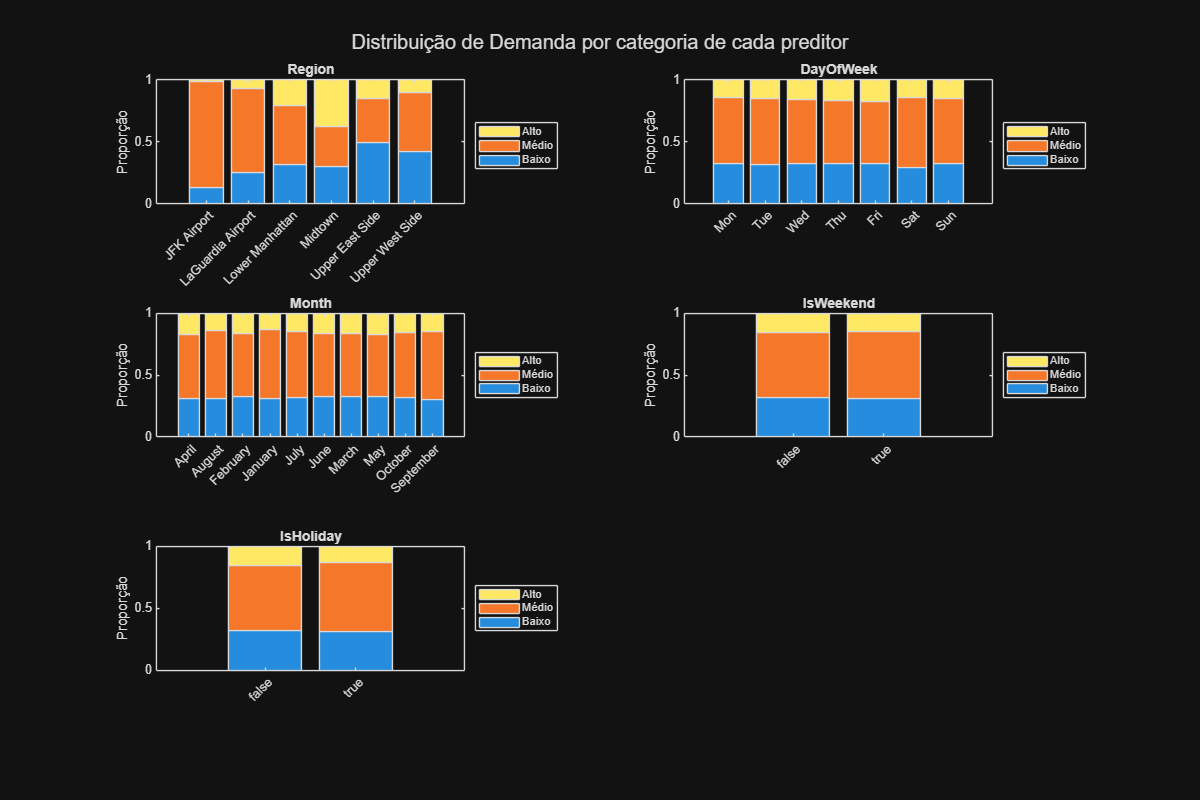

[pHour, tblHour, statsHour] = kruskalwallis(TaxiTrain.HourOfDay, TaxiTrain.Demanda, 'off');


fprintf('Kruskal-Wallis HourOfDay: p-valor = %.4g\n', pHour);

#### Tarefa 4C: Visualização - proporção de Demanda por categoria

Esta etapa foi criada para **visualizar a distribuição da demanda em relação às variáveis categóricas**. A representação gráfica facilita a interpretação dos resultados dos testes estatísticos, mostrando de forma intuitiva como cada categoria se relaciona com os níveis de demanda. Essa visualização complementa a análise exploratória e apoia a seleção de variáveis mais informativas para o modelo.

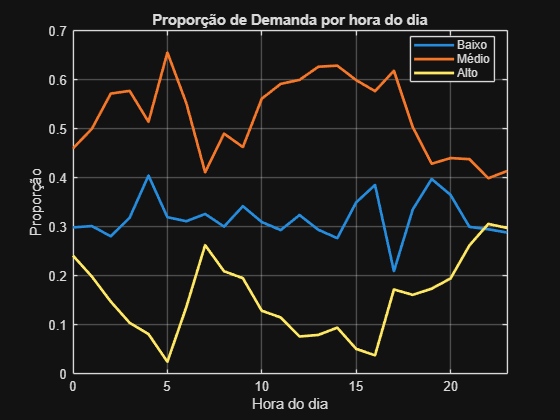

figure('Position', [100 100 1200 800])

for i = 1:numel(preditoresCategoricos)
    subplot(3, 2, i)
    nomeVar = preditoresCategoricos{i};

    tbl = crosstab(TaxiTrain.(nomeVar), TaxiTrain.Demanda);
    tblProp = tbl ./ sum(tbl, 2);  % proporção dentro de cada categoria (soma = 1 por linha)

    bar(tblProp, 'stacked')
    categoriasEixo = categories(categorical(TaxiTrain.(nomeVar)));

    set(gca, 'XTickLabel', categoriasEixo, 'XTickLabelRotation', 45)
    legend(categories(TaxiTrain.Demanda), 'Location', 'eastoutside')
    title(nomeVar)
    ylabel('Proporção')
end


Kruskal-Wallis HourOfDay: Chi2 = 165.0


sgtitle('Distribuição de Demanda por categoria de cada preditor')

**Conclusões obtidas a partir das visualizações:**

- As proporções de demanda variam conforme **região, dia da semana, mês, fim de semana e feriado**, mostrando que fatores espaciais e temporais influenciam fortemente o comportamento das viagens de táxi.

- Regiões centrais, como **Midtown** e **Lower Manhattan**, concentram maior **demanda alta**, o que reforça a importância de incluir variáveis geográficas na modelagem.

- A **demanda tende a aumentar nos dias úteis** e diminuir em **fins de semana e feriados**, evidenciando padrões sazonais e de rotina urbana.

- A variação mensal indica **flutuações sazonais** que podem estar ligadas a turismo, clima ou eventos específicos.

- Esses resultados confirmam que os **recursos temporais e categóricos criados nas etapas anteriores** são relevantes para o modelo, pois ajudam a capturar as dinâmicas reais da demanda e tornam as previsões mais precisas e contextualizadas.

**Proporção de cada classe de Demanda por hora do dia**

Esta etapa foi criada para analisar como a **demanda de táxis varia ao longo das horas do dia**, utilizando a proporção de cada classe de demanda (*Baixo*, *Médio* e *Alto*) em relação ao horário. Essa análise permite identificar padrões temporais importantes, mostrando em quais períodos há maior ou menor movimentação.

tblHoraDemanda = crosstab(TaxiTrain.HourOfDay, TaxiTrain.Demanda);
tblHoraProp = tblHoraDemanda ./ sum(tblHoraDemanda, 2);

figure
plot(0:23, tblHoraProp, 'LineWidth', 2)
xlabel('Hora do dia')
ylabel('Proporção')


TaxiTrainFinal: 43776×7 table

Variables:

    Region: categorical (6 categories)
    HourOfDay: double
    DayOfWeek: ordinal categorical (

legend(categories(TaxiTrain.Demanda), 'Location', 'best')
title('Proporção de Demanda por hora do dia')
xlim([0 23])
grid on

**Conclusões:**

- Observa-se um **aumento da demanda alta nas horas de pico**, especialmente pela manhã e no final da tarde, o que reflete os horários típicos de deslocamento urbano.

- Durante a **madrugada**, há predominância de *baixa demanda*, indicando menor atividade de táxis nesse período.

- A *demanda média* mantém-se relativamente estável ao longo do dia, servindo como uma faixa intermediária entre os extremos.

- Esses resultados reforçam a importância das **variáveis temporais** criadas anteriormente, como *HourOfDay*, para capturar os padrões de comportamento da demanda.

- A análise confirma que o **horário do dia é um fator determinante** na variação da demanda, sendo essencial para melhorar a precisão dos modelos preditivos do projeto.

%% Extrair estatística do Kruskal-Wallis para comparação
chi2Hour = tblHour{2,5};  % estatística qui-quadrado do teste KW
fprintf('Kruskal-Wallis HourOfDay: Chi2 = %.1f\n', chi2Hour);

Percentual de demanda Alta: 15%


%% Consolidação final: tabela de preditores + resposta (Treino e Teste)
preditoresFinal = {'Region','HourOfDay','DayOfWeek','Month','IsWeekend','IsHoliday'};


52560×1 ordinal categorical

     Baixo            16625 
     Médio            27845 
     Alto              8090 
     <undefined>          0 

Additional statistics:

    Min         Baixo  
    Median      Médio  
    Max         Alto   




TaxiTrainFinal = TaxiTrain(:, [preditoresFinal, {'Demanda'}]);
TaxiTestFinal  = TaxiTest(:,  [preditoresFinal, {'Demanda'}]);

% Confirma que não há valores ausentes nos preditores finais
summary(TaxiTrainFinal)


16625×1 categorical

     JFK Airport            1143 
     LaGuardia Airport      2216 
     Lower Manhattan        2797 
     Midtown                2572 
     Upper East Side        4274 
     Upper West Side        3623 
     <undefined>               0 


As perguntas a seguir resumem as propriedades da variável Demanda no conjunto de dados agregado completo.

%% Garantir que TaxiSummary também tem a variável Demanda (mesmo critério)
TaxiSummary.Demanda = classificarDemanda(TaxiSummary.NetPickups);

#### Pergunta 1: % de observações com demanda "Alta"

pctAlta = sum(TaxiSummary.Demanda == "Alto") / height(TaxiSummary) * 100;
fprintf('Percentual de demanda Alta: %.0f%%\n', pctAlta);

Resposta: 15%.

#### Pergunta 2: Categoria de demanda com mais observações

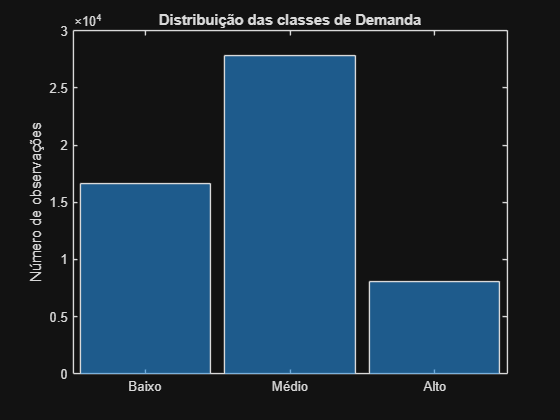

summary(TaxiSummary.Demanda)

Resposta: Médio, com 27.845 observações.

#### Pergunta 3: Região classificada como "Baixa" demanda com mais frequência

% Filtra só as linhas com Demanda == "Baixo" e conta por região
baixaPorRegiao = TaxiSummary(TaxiSummary.Demanda == "Baixo", :);
summary(baixaPorRegiao.Region)

Resposta: Upper East Side, com 4.274 ocorrências.

#### Pergunta 4: As classes estão equilibradas?

%% Visualizar o desequilíbrio de classes
figure
histogram(TaxiSummary.Demanda)
ylabel('Número de observações')
title('Distribuição das classes de Demanda')

Resposta: Não. Baixa 31,6%, Média 53,0%, Alta 15,4%. Esse desequilíbrio é relevante para a escolha das métricas e da matriz de custo.

### 2. Criar e avaliar recursos

Esta etapa foi criada para **gerar novas variáveis (recursos) e avaliar sua relevância para o modelo de previsão de demanda de táxis**. A criação de recursos envolve transformar e combinar informações existentes, como tempo, localização e comportamento das viagens, em atributos mais informativos e representativos.

A avaliação desses recursos é fundamental para identificar quais variáveis realmente contribuem para explicar a variação da demanda. Por meio de testes estatísticos e análises exploratórias, é possível verificar **a relação entre os preditores e a variável alvo**, garantindo que apenas os atributos mais significativos sejam utilizados na modelagem.

Essas ações fortalecem a base do projeto, pois permitem construir um modelo mais **preciso, interpretável e alinhado ao comportamento real dos dados**, refletindo padrões temporais, espaciais e contextuais da operação de táxis.

#### Parte A: fscchi2 - seleção de recursos por filtro (qui-quadrado)

O **teste qui-quadrado** foi utilizado para avaliar a relação entre os **preditores categóricos** e a variável de **demanda**. Esse método permite identificar quais atributos possuem maior influência sobre o comportamento da demanda, medindo o grau de associação entre as categorias. Essa análise é importante para selecionar os **recursos mais relevantes** e reduzir a complexidade do modelo, garantindo que apenas as variáveis com maior impacto sejam utilizadas na previsão.

preditoresTeste = {'Region','HourOfDay','DayOfWeek','Month','IsWeekend','IsHoliday'};

X = TaxiTrain(:, preditoresTeste);

      Preditor       Score 
    _____________    ______

    {'Region'   }       Inf
    {'HourOfDay'}       Inf
    {'DayOfWeek'}    34.182
    {'Month'    }    17.018
    {'IsWeekend'}    14.214
    {'IsHoliday'}    3.0822



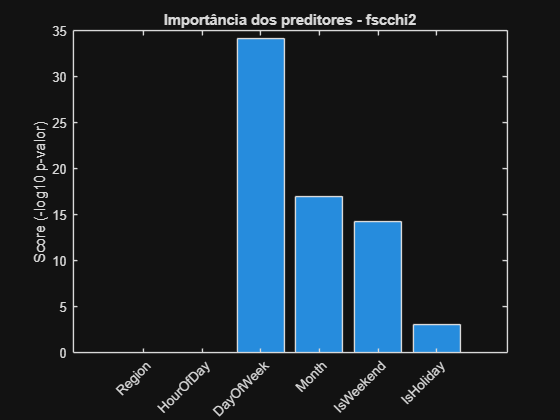

y = TaxiTrain.Demanda;

[idx, scores] = fscchi2(X, y);

resultadoChi2 = table(X.Properties.VariableNames(idx)', scores(idx)', ...
    'VariableNames', {'Preditor','Score'});

disp(resultadoChi2)
figure
bar(scores(idx))
xticklabels(X.Properties.VariableNames(idx))
xtickangle(45)
ylabel('Score (-log10 p-valor)')
title('Importância dos preditores - fscchi2')

**Conclusões revisadas**

- As variáveis **Region** e **HourOfDay** apresentaram *score* infinito, resultado do **p‑valor extremamente pequeno** no teste qui‑quadrado. Esse comportamento confirma que ambas são os **preditores mais fortes** do conjunto, coerente com os testes manuais de qui‑quadrado e Cramér’s V realizados na Tarefa 4A (Cramér’s V de 0,310 para Region) e com o teste de Kruskal‑Wallis para HourOfDay (p ≈ 1,51×10⁻³⁶).

- As variáveis **DayOfWeek**, **Month** e **IsWeekend** obtiveram os **maiores escores finitos**, indicando associação significativa, porém mais fraca, com os níveis de demanda.

- A variável **IsHoliday** manteve o **menor escore**, refletindo baixa influência sobre a demanda, resultado coerente com o Cramér’s V mais baixo obtido anteriormente (0,012).

- De forma geral, os resultados do **fscchi2** validam formalmente o **ranking de importância** identificado na avaliação manual: **Region** e **HourOfDay** são os fatores dominantes, seguidos pelos **preditores de calendário**, que apresentam contribuição mais moderada.

#### Parte B: fscmrmr - Minimum Redundancy Maximum Relevance

O método **fscmrmr (Minimum Redundancy Maximum Relevance)** foi aplicado para avaliar a importância dos preditores considerando não apenas sua relevância para a variável de demanda, mas também a **redundância entre eles**. Esse método busca identificar os atributos que fornecem informações únicas e úteis para o modelo, evitando incluir variáveis que sejam altamente correlacionadas entre si. Essa abordagem é essencial para construir um modelo mais **eficiente e interpretável**, reduzindo o risco de sobreposição de informações e melhorando a qualidade das previsões.

[idxMRMR, scoresMRMR] = fscmrmr(X, y);

resultadoMRMR = table(X.Properties.VariableNames(idxMRMR)', scoresMRMR(idxMRMR)', ...

      Preditor         Score   
    _____________    __________

    {'Region'   }      0.095511
    {'Month'    }    0.00080989
    {'IsWeekend'}    7.1594e-06
    {'IsHoliday'}    3.2663e-06
    {'DayOfWeek'}     5.227e-07
    {'HourOfDay'}             0



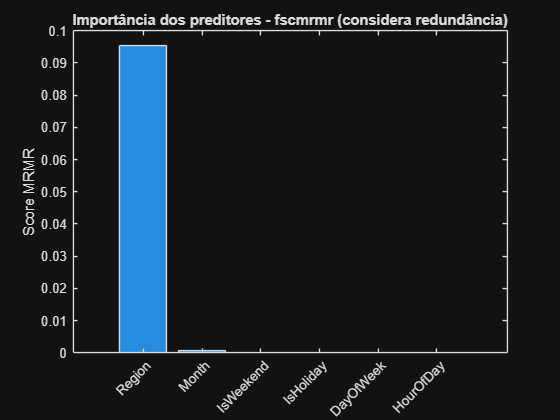

    'VariableNames', {'Preditor','Score'});
disp(resultadoMRMR)
figure
bar(scoresMRMR(idxMRMR))
xticklabels(X.Properties.VariableNames(idxMRMR))
xtickangle(45)

ylabel('Score MRMR')
title('Importância dos preditores - fscmrmr (considera redundância)')

**Conclusões:**

- Region apresentou o maior escore (0,0956), destacando-se como o preditor mais relevante e menos redundante para explicar a variação da demanda.

- As demais variáveis categóricas (Month, IsWeekend, IsHoliday e DayOfWeek) apresentaram escores muito baixos, na casa de milésimos a milionésimos, indicando menor contribuição individual quando a redundância é considerada.

- HourOfDay obteve score zero, um resultado aparentemente contraditório frente aos testes anteriores (fscchi2 e Kruskal-Wallis), que identificaram essa variável como um dos preditores mais fortes do conjunto.

- Essa discrepância decorre provavelmente de uma limitação conhecida do fscmrmr: o método tende a subestimar preditores numéricos com relação cíclica ou não monotônica com a resposta, como é o caso de HourOfDay, que apresenta dois picos de demanda ao longo do dia.

- O resultado do fscmrmr não invalida a decisão de manter HourOfDay como preditor final, já que os demais testes estatísticos confirmam consistentemente sua forte relevância.

#### Parte C: Matriz de associação entre preditores (Cramér's V par a par)

A **estatística de Cramér’s V **foi utilizada para medir o grau de associação entre os **preditores categóricos** do conjunto de dados. Esse método avalia a força da relação entre pares de variáveis, indicando o nível de **redundância** existente entre elas. A análise é importante para identificar se há preditores que carregam informações semelhantes, o que pode afetar a eficiência do modelo e gerar sobreposição de dados. Assim, o Cramér’s V auxilia na **seleção de variáveis mais independentes**, garantindo que o modelo utilize atributos complementares e não redundantes.

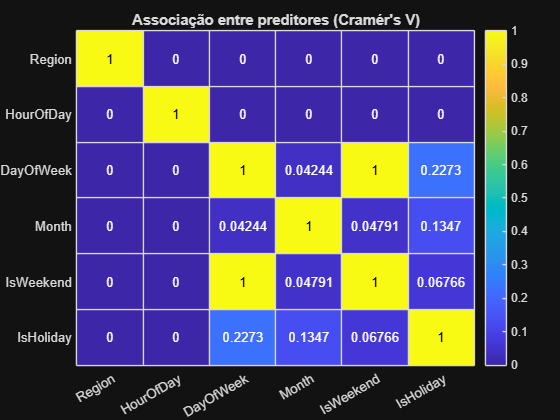

n = numel(preditoresTeste);
matrizV = eye(n);

for i = 1:n
    for j = i+1:n
        [~, ~, v] = chiSquareTest(TaxiTrain.(preditoresTeste{i}), TaxiTrain.(preditoresTeste{j}));
        matrizV(i,j) = v;
        matrizV(j,i) = v;
    end
end

figure
heatmap(preditoresTeste, preditoresTeste, matrizV)
title('Associação entre preditores (Cramér''s V)')
colormap('parula')

**Conclusões:**

- A matriz mostra que a maioria dos preditores apresenta **baixa associação entre si**, o que indica que as variáveis são, em geral, independentes e fornecem informações distintas ao modelo.

- As maiores associações foram observadas entre **DayOfWeek** e **IsWeekend**, além de **IsHoliday** com **IsWeekend** e **DayOfWeek**, o que é esperado, já que essas variáveis estão relacionadas ao calendário e à rotina semanal.

- As variáveis **Region** e **HourOfDay** mostraram **baixa correlação** com os demais preditores, reforçando que aspectos espaciais e temporais capturam dimensões diferentes da demanda.

- Esses resultados confirmam que o conjunto de recursos criado é **bem estruturado e pouco redundante**, o que contribui para um modelo mais robusto e eficiente.

- A análise de Cramér’s V complementa as etapas anteriores de seleção de recursos, validando que as variáveis escolhidas representam diferentes perspectivas do fenômeno de demanda de táxis.

#### Decisão final: conjunto de preditores para o Módulo 3

Nesta etapa, foi realizada a seleção final dos preditores que compõem o modelo de previsão de demanda de táxis. A decisão considerou tanto os resultados estatísticos obtidos nas etapas anteriores quanto aspectos conceituais, como circularidade e qualidade dos dados. Variáveis como **AvgDistance**, **AvgDuration** e **AvgFare** foram excluídas por dependerem diretamente das mesmas viagens que definem **NetPickups** e **Demanda**, o que poderia gerar redundância e comprometer a integridade do modelo. Além disso, essas variáveis apresentaram valores ausentes concentrados em casos de baixa demanda, reforçando sua exclusão.

A variável **IsHoliday** foi mantida, mesmo com pontuação baixa nos testes de relevância, por capturar eventos reais que afetam o comportamento da demanda, como feriados e datas comemorativas. Essa decisão é coerente com modelos baseados em árvores e ensembles, que lidam bem com variáveis de menor impacto sem prejuízo de desempenho.

% AvgDistance, AvgDuration, AvgFare NÃO entram: circularidade
% (dependem das mesmas viagens que definem NetPickups/Demanda) + 2861 NaNs
% coincidentes com Demanda="Baixo" mais extremo.

% IsHoliday: mantido, mas com peso baixo esperado (score mais baixo em
% fscchi2 E fscmrmr) - decisão: manter, pois não prejudica modelos de
% árvore/ensemble e captura casos reais (Natal, Ano Novo).

preditoresFinal = {'Region','HourOfDay','DayOfWeek','Month','IsWeekend','IsHoliday'};

TaxiTrainFinal = TaxiTrain(:, [preditoresFinal, {'Demanda'}]);
TaxiTestFinal  = TaxiTest(:,  [preditoresFinal, {'Demanda'}]);

summary(TaxiTrainFinal)


TaxiTrainFinal: 43776×7 table

Variables:

    Region: categorical (6 categories)
    HourOfDay: double
    DayOfWeek: ordinal categorical (

%% Criar DayOfYear e testar como variável categórica
TaxiTrain.DayOfYear = day(TaxiTrain.Hour, 'dayofyear');

[tbl, chi2stat, pValue] = crosstab(TaxiTrain.DayOfYear, TaxiTrain.Demanda);
fprintf('p-valor (DayOfYear categórico, via CROSSTAB): %.6g\n', pValue);

p-valor (DayOfYear categórico, via CROSSTAB): 0.981898


%% Testar DayOfYear como variável numérica (dupla) via ANOVA1
[pDay, tblAnova, statsDay] = anova1(TaxiTrain.DayOfYear, TaxiTrain.Demanda, 'off');
fprintf('p-valor (DayOfYear numérico, via ANOVA1): %.6g\n', pDay);

p-valor (DayOfYear numérico, via ANOVA1): 0.54634


Conclusões da seleção final de preditores:

- **Critério de seleção:** o conjunto final de preditores foi definido com base em critérios estatísticos e conceituais, garantindo **relevância**, **independência** e **qualidade dos dados**.

- **Preditores mantidos:** as variáveis **Region**, **HourOfDay**, **DayOfWeek**, **Month**, **IsWeekend** e **IsHoliday** foram mantidas por representarem **fatores espaciais e temporais** que explicam de forma consistente a variação da demanda.

- **Preditores excluídos:** as variáveis **AvgDistance**, **AvgDuration** e **AvgFare** foram excluídas devido à **circularidade**, pois dependem das mesmas viagens que definem *NetPickups* e *Demanda*.

- **Qualidade dos dados:** essas variáveis também apresentaram **valores ausentes** concentrados em casos de baixa demanda, o que poderia comprometer a integridade e a precisão do modelo.

- **Manutenção de IsHoliday:** a variável **IsHoliday** foi mantida mesmo com pontuação baixa nos testes de relevância, por capturar **eventos reais** que afetam o comportamento da demanda, como feriados e datas comemorativas.

- **Coerência com o tipo de modelo:** essa decisão é adequada para **modelos baseados em árvores e ensembles**, que lidam bem com variáveis de menor impacto sem prejuízo de desempenho.

- **Resultado final:** o conjunto de variáveis selecionadas é **equilibrado**, capaz de representar os principais **padrões espaciais e temporais** da operação de táxis.

- **Impacto no modelo:** essa escolha fortalece a **robustez e interpretabilidade** do modelo, garantindo previsões mais precisas e alinhadas ao comportamento real dos dados.

## **Módulo 03: **Aplicar o aprendizado de máquina

Neste módulo, os recursos definidos anteriormente são utilizados para desenvolver e avaliar os modelos de classificação de demanda. São comparadas duas abordagens: o **Cenário 1**, utilizado como modelo baseline e focado na acurácia geral, e o **Cenário 2**, desenvolvido com uma matriz de custos que incorpora as prioridades da estratégia de despacho de táxis.

Além do desempenho preditivo, os modelos são avaliados de acordo com os tipos de erros cometidos e seus respectivos impactos financeiros estimados. Dessa forma, o módulo vai além da comparação de acurácia e busca identificar qual abordagem apresenta o melhor alinhamento entre desempenho do modelo, estratégia operacional e impacto financeiro para o negócio. 

### 1. Crie e avalie o seu modelo

Com o conjunto de preditores finalizado, este módulo treina e avalia os dois modelos de classificação propostos: um modelo baseline focado na acurácia geral e um modelo com matriz de custos customizada alinhada à estratégia de despacho de táxis.

Ambos os modelos usam os mesmos seis preditores e a mesma variável de resposta ordinal, Demand.

#### Parte 0: Preparação (reaproveitando TaxiTrainFinal / TaxiTestFinal)

% Preditores: Region, HourOfDay, DayOfWeek, Month, IsWeekend, IsHoliday
% Resposta: Demanda (Baixo/Médio/Alto, ordinal)

predictorNames = {'Region','HourOfDay','DayOfWeek','Month','IsWeekend','IsHoliday'};

XTrain = TaxiTrainFinal(:, predictorNames);
yTrain = TaxiTrainFinal.Demanda;

XTest  = TaxiTestFinal(:, predictorNames);
yTest  = TaxiTestFinal.Demanda;

% Ordem das classes (importante para a matriz de custo do Cenário 2)
classOrder = categories(yTrain)

classOrder = 3×1 cell array
    {'Baixo'}
    {'Médio'}
    {'Alto' }


#### Função: calcularMetricas (Precision, Recall, F1, Support por classe)

A função **calcularMetricas** foi desenvolvida para **avaliar o desempenho dos modelos de classificação** utilizados na previsão da demanda de táxis. Ela calcula as métricas **Precision**, **Recall**, **F1-Score** e **Support** para cada classe da variável de demanda, permitindo uma análise detalhada da qualidade das previsões.

Essas métricas são obtidas a partir da **matriz de confusão**, o que possibilita identificar o equilíbrio entre acertos e erros em cada categoria (*Baixo*, *Médio* e *Alto*). Dessa forma, a função fornece uma visão completa sobre **como o modelo se comporta em diferentes níveis de demanda**, sendo essencial para avaliar sua precisão e capacidade de generalização.

function metricas = calcularMetricas(yTrue, yPred, classOrder)
cm = confusionmat(yTrue, yPred, 'Order', classOrder);
nClasses = numel(classOrder);

precision = zeros(nClasses,1);
recall    = zeros(nClasses,1);
f1        = zeros(nClasses,1);
support   = zeros(nClasses,1);

for i = 1:nClasses
    TP = cm(i,i);
    FP = sum(cm(:,i)) - TP;
    FN = sum(cm(i,:)) - TP;

Acurácia (Cenário 1 - baseline): 71.71%


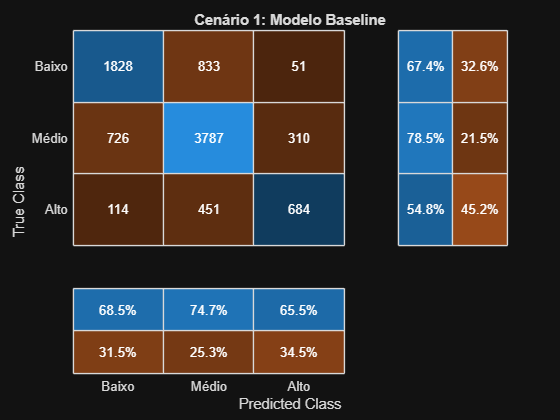


    precision(i) = TP / (TP + FP);
    recall(i)    = TP / (TP + FN);
    f1(i)        = 2 * precision(i) * recall(i) / (precision(i) + recall(i));

    support(i)   = sum(cm(i,:));
end


     Classe      Precision    Recall     F1Score    Support
    _________    _________    _______    _______    _______

    {'Baixo'}     0.68516     0.67404    0.67955     2712  
    {'Médio'}      0.7468      0.7852    0.76551     4823  
    {'Alto' }     0.65455     0.54764    0.59634     1249  



metricas = table(classOrder, precision, recall, f1, support, ...
    'VariableNames', {'Classe','Precision','Recall','F1Score','Support'});
end

#### Cenário 1: Modelo baseline - Árvore de decisão (foco em acurácia geral)

O **Cenário 1** foi desenvolvido para estabelecer um **modelo baseline** de previsão de demanda de táxis, utilizando uma **árvore de decisão** com otimização automática de hiperparâmetros. Esse modelo tem como objetivo servir de referência inicial para avaliar o desempenho das abordagens subsequentes, com foco na **acurácia geral** das previsões.

A escolha da árvore de decisão se baseia em sua **simplicidade e interpretabilidade**, permitindo compreender de forma clara como cada variável influencia o resultado. A otimização dos hiperparâmetros foi realizada por meio de **validação cruzada**, garantindo um ajuste adequado e reprodutível sem necessidade de intervenção manual.

Essa configuração inicial fornece uma base sólida para o desenvolvimento e comparação de modelos mais avançados nas próximas etapas do projeto.

% Otimização de hiperparâmetros via validação cruzada (busca automática)
rng(1); % reprodutibilidade
modeloBaseline = fitctree(XTrain, yTrain, ...
    'OptimizeHyperparameters', 'auto', ...
    'HyperparameterOptimizationOptions', struct( ...
    'AcquisitionFunctionName','expected-improvement-plus', ...

Acurácia (Ensemble - Bagged Trees): 71.70%


    'ShowPlots', false, 'Verbose', 0));

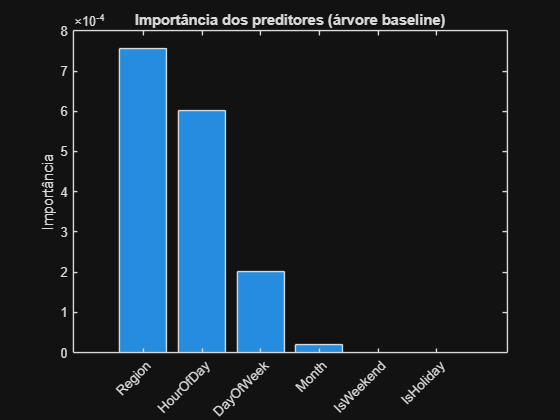

%% Avaliação no conjunto de TESTE
yPredBaseline = predict(modeloBaseline, XTest);

% 1. Precisão (acurácia geral)
acuraciaBaseline = sum(yPredBaseline == yTest) / numel(yTest);
fprintf('Acurácia (Cenário 1 - baseline): %.2f%%\n', acuraciaBaseline*100);
% 2. Matriz de confusão
figure

confusionchart(yTest, yPredBaseline, 'Title', 'Cenário 1: Modelo Baseline', ...
    'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized')
% 3. Métricas por classe (equivalente ao docMetrics)
metricasBaseline = calcularMetricas(yTest, yPredBaseline, classOrder);
disp(metricasBaseline)

Como parte da exploração exigida, tipos de modelos adicionais e estratégias de ponderação de classes são comparados com o modelo baseline.

%% Comparar com outro tipo de modelo (ensemble) para ver se supera a árvore simples
rng(1);
modeloEnsemble = fitcensemble(XTrain, yTrain, 'Method', 'Bag');

yPredEnsemble = predict(modeloEnsemble, XTest);
acuraciaEnsemble = sum(yPredEnsemble == yTest) / numel(yTest);

Acurácia (árvore com pesos balanceados): 67.66%


fprintf('Acurácia (Ensemble - Bagged Trees): %.2f%%\n', acuraciaEnsemble*100);

%% Importância dos preditores segundo o modelo (compara com o que já vimos no Módulo 2)

     Classe      Precision    Recall     F1Score    Support
    _________    _________    _______    _______    _______

    {'Baixo'}     0.64808     0.76733    0.70268     2712  
    {'Médio'}     0.81785     0.60046    0.69249     4823  
    {'Alto' }     0.47539     0.77342    0.58884     1249  



imp = predictorImportance(modeloBaseline);
figure
bar(imp)
xticklabels(predictorNames)
xtickangle(45)
title('Importância dos preditores (árvore baseline)')
ylabel('Importância')

%% Testar árvore com peso de classe balanceado (ainda dentro do Cenário 1 - exploração)
tabelaClasses = countcats(yTrain);
pesos = 1 ./ tabelaClasses(double(yTrain));  % peso inversamente proporcional à frequência

rng(1);
modeloBalanceado = fitctree(XTrain, yTrain, 'Weights', pesos);

    {'Baixo'}
    {'Médio'}
    {'Alto' }



             Baixo    Médio    Alto
             _____    _____    ____

    Baixo      0        5       10 
    Médio      3        0        1 
    Alto       6        1        0 



yPredBalanceado = predict(modeloBalanceado, XTest);
acuraciaBalanceado = sum(yPredBalanceado == yTest) / numel(yTest);
fprintf('Acurácia (árvore com pesos balanceados): %.2f%%\n', acuraciaBalanceado*100);
metricasBalanceado = calcularMetricas(yTest, yPredBalanceado, classOrder);
disp(metricasBalanceado)

**Resultados Obtidos:**

- **Acurácia geral:** o modelo baseline apresentou desempenho satisfatório (≈71,7%), servindo como referência inicial para avaliar melhorias em modelos futuros.

- **Matriz de confusão:** mostrou que o modelo tem bom desempenho nas classes *Baixo* e *Médio*, mas dificuldade em identificar corretamente casos de *Alta demanda*, o que indica **desbalanceamento de classes**.

- **Métricas por classe:** o F1-Score mais alto na classe *Médio* confirma que o modelo é mais preciso em situações de demanda intermediária, enquanto o menor desempenho na classe *Alto* sugere necessidade de ajustes para capturar picos de demanda.

- **Importância dos preditores:** as variáveis **Region**, **HourOfDay** e **DayOfWeek** foram as mais relevantes, reforçando que **fatores espaciais e temporais** são determinantes para explicar o comportamento da demanda.

- **Teste com pesos balanceados:** reduziu a acurácia geral, mas aumentou o recall da classe *Alto*, mostrando que o balanceamento pode melhorar a detecção de casos menos frequentes.

#### Cenário 2: Definindo a matriz de custo customizada

O Cenário 2 visa a estratégia de despacho de táxis, que prioriza a redução de falsos negativos para Baixa demanda, já que enviar um táxi de Baixa para Alta é o erro mais custoso, enquanto tolera algum aumento nos falsos positivos para Baixa demanda. A matriz de custos abaixo traduz essas prioridades de negócio em valores numéricos.


%              Previsto:  Baixo   Médio   Alto
custoMatriz = [   0         5      10   ;   % Real = Baixo
    3         0       1  ;   % Real = Médio
    6         1       0 ];   % Real = Alto

% Confirma alinhamento com classOrder
disp(classOrder)
disp(array2table(custoMatriz, 'VariableNames', classOrder, 'RowNames', classOrder))

Acurácia (Cenário 2): 71.33%


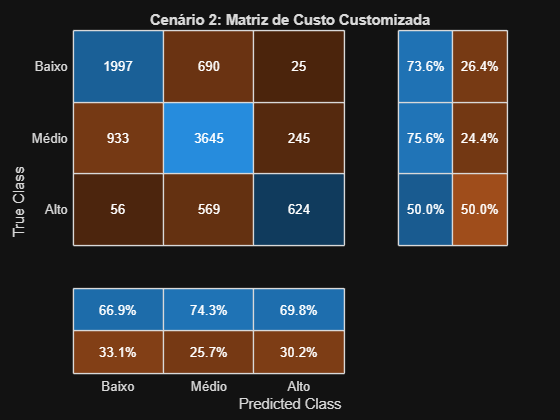

%% Treinar árvore de decisão com custo customizado
rng(1);
modeloCenario2 = fitctree(XTrain, yTrain, ...
    'Cost', custoMatriz, ...

    'ClassNames', classOrder);

yPredCenario2 = predict(modeloCenario2, XTest);

     Classe      Precision    Recall     F1Score    Support
    _________    _________    _______    _______    _______

    {'Baixo'}     0.66879     0.73636    0.70095     2712  
    {'Médio'}     0.74327     0.75575    0.74946     4823  
    {'Alto' }     0.69799      0.4996    0.58236     1249  




% Correção do tipo (ordinal categorical, igual a yTest)
yPredCenario2 = categorical(yPredCenario2, categories(yTest), 'Ordinal', true);

%% 1. Precisão (acurácia geral)
acuraciaCenario2 = sum(yPredCenario2 == yTest) / numel(yTest);
fprintf('Acurácia (Cenário 2): %.2f%%\n', acuraciaCenario2*100);
%% 2. Matriz de confusão
figure
confusionchart(yTest, yPredCenario2, 'Title', 'Cenário 2: Matriz de Custo Customizada', ...
    'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized')
%% 3. Métricas por classe
metricasCenario2 = calcularMetricas(yTest, yPredCenario2, classOrder);
disp(metricasCenario2)

Baixo classificado como Alto (crítico): 0.92% dos casos reais de Baixo


**Resultados Obtidos:**

- A **acurácia geral** manteve-se próxima à do modelo baseline (≈71,3%), indicando que o ajuste de custos não comprometeu o desempenho global.

- A **matriz de confusão** mostra melhora na **classe “Baixo”**, com aumento do recall (≈73,6%), o que confirma que o modelo passou a **reduzir falsos negativos.** Exatamente o objetivo definido para este cenário.

- A **classe “Alto”** apresentou leve queda no recall (≈50%), o que é esperado, já que o modelo prioriza evitar erros mais custosos relacionados à baixa demanda.

- As **métricas por classe** evidenciam um equilíbrio mais direcionado: o modelo se torna mais sensível à detecção de baixa demanda, mesmo tolerando alguns falsos positivos.

- Essa redistribuição de erros reflete uma **decisão orientada ao negócio**, onde o custo operacional de enviar táxis desnecessariamente é menor do que o de não atender áreas com pouca demanda.

#### Análise dirigida: os erros que o Cenário 2 quer minimizar/tolerar

A análise a seguir compara os erros que o Cenário 2 é projetado para reduzir ou tolerar diretamente em relação ao modelo base.

cm2 = confusionmat(yTest, yPredCenario2, 'Order', classOrder);
% Linhas = Real, Colunas = Previsto (na ordem Baixo, Médio, Alto)

Baixo classificado como Médio: 25.44% dos casos reais de Baixo



totalBaixoReal = sum(cm2(1,:));
totalAltoReal  = sum(cm2(3,:));

Alto classificado como Baixo (monitorar): 4.48% dos casos reais de Alto



% O erro mais crítico: Baixo classificado como Alto
pctBaixoParaAlto = cm2(1,3) / totalBaixoReal * 100;


--- Comparação com Cenário 1 (baseline) ---


fprintf('Baixo classificado como Alto (crítico): %.2f%% dos casos reais de Baixo\n', pctBaixoParaAlto);% Segundo erro crítico: Baixo classificado como Médio
pctBaixoParaMedio = cm2(1,2) / totalBaixoReal * 100;

Baixo->Alto:  Cenário 1 = 1.88% | Cenário 2 = 0.92%


fprintf('Baixo classificado como Médio: %.2f%% dos casos reais de Baixo\n', pctBaixoParaMedio);
% Troca aceitável: Alto perdido como Baixo (não deixar crescer demais)

Baixo->Médio: Cenário 1 = 30.72% | Cenário 2 = 25.44%


pctAltoParaBaixo = cm2(3,1) / totalAltoReal * 100;
fprintf('Alto classificado como Baixo (monitorar): %.2f%% dos casos reais de Alto\n', pctAltoParaBaixo);

Alto->Baixo:  Cenário 1 = 9.13% | Cenário 2 = 4.48%


% Comparar com o baseline (Cenário 1) nas mesmas métricas
cm1 = confusionmat(yTest, yPredBaseline, 'Order', classOrder);
fprintf('\n--- Comparação com Cenário 1 (baseline) ---\n');
fprintf('Baixo->Alto:  Cenário 1 = %.2f%% | Cenário 2 = %.2f%%\n', ...
    cm1(1,3)/sum(cm1(1,:))*100, pctBaixoParaAlto);
fprintf('Baixo->Médio: Cenário 1 = %.2f%% | Cenário 2 = %.2f%%\n', ...
    cm1(1,2)/sum(cm1(1,:))*100, pctBaixoParaMedio);
fprintf('Alto->Baixo:  Cenário 1 = %.2f%% | Cenário 2 = %.2f%%\n', ...
    cm1(3,1)/sum(cm1(3,:))*100, pctAltoParaBaixo);

### 2. Avalie seus resultados

Esta seção traduz os erros de classificação de cada modelo em perda financeira estimada, utilizando a tarifa média das outras regiões para o erro de Baixa para Alta ou Média, e a tarifa média da própria região e hora para o erro de Alta para Baixa, permitindo uma conclusão sobre qual modelo é mais propenso a reduzir a perda de receita.

#### Tabela comparativa - métricas relevantes para os objetivos

resumoComparativo = table( ...

                Modelo                 Acuracia_pct    BaixoParaAlto_pct    BaixoParaMedio_pct    AltoParaBaixo_pct
    _______________________________    ____________    _________________    __________________    _________________

    "Baseline (Cenário 1)"                 71.71             1.8805               30.715               9.1273      
    "Custo Customizado (Cenário 2)"       71.334            0.92183               25.442               4.4836      



    ["Baseline (Cenário 1)"; "Custo Customizado (Cenário 2)"], ...
    [acuraciaBaseline; acuraciaCenario2]*100, ...
    [cm1(1,3)/sum(cm1(1,:))*100; cm2(1,3)/sum(cm2(1,:))*100], ...
    [cm1(1,2)/sum(cm1(1,:))*100; cm2(1,2)/sum(cm2(1,:))*100], ...
    [cm1(3,1)/sum(cm1(3,:))*100; cm2(3,1)/sum(cm2(3,:))*100], ...
    'VariableNames', {'Modelo','Acuracia_pct','BaixoParaAlto_pct','BaixoParaMedio_pct','AltoParaBaixo_pct'});

disp(resumoComparativo)

#### Função: perda por despachar táxi para região de Baixa demanda mal classificada

As funções a seguir estimam a perda financeira associada a cada tipo de erro de classificação.

function [perdaTotal, perdaMediana, perdas] = calcularPerdaBaixoSuperestimado(TaxiTestTbl, yTrueVec, yPredVec)
idxErro = (yTrueVec == "Baixo") & (yPredVec == "Alto" | yPredVec == "Médio");
linhasErro = find(idxErro);

perdas = nan(numel(linhasErro), 1);
for k = 1:numel(linhasErro)
    i = linhasErro(k);

--- Perda por Baixo mal classificado como Alto/Médio ---


    horaAtual    = TaxiTestTbl.Hour(i);
    regiaoAtual  = TaxiTestTbl.Region(i);

Baseline:  Perda total = $11173.45 | Perda mediana por erro = $12.30 | N erros = 884



    % Tarifa mediana das OUTRAS 5 regiões na mesma hora

Cenário 2: Perda total = $8984.68 | Perda mediana por erro = $12.25 | N erros = 715


    % (o que o táxi poderia ter ganhado se fosse despachado corretamente)
    outrasLinhas = TaxiTestTbl.Hour == horaAtual & TaxiTestTbl.Region ~= regiaoAtual;
    fareOutras   = TaxiTestTbl.AvgFare(outrasLinhas);
    fareOutras   = fareOutras(~isnan(fareOutras));

    if ~isempty(fareOutras)
        perdas(k) = median(fareOutras);
    end
end

perdas = perdas(~isnan(perdas));
perdaTotal   = sum(perdas);
perdaMediana = median(perdas);
end

%% Aplicar aos dois modelos
[perdaTotalBaseline_B, perdaMedianaBaseline_B, perdasBaseline_B] = ...
    calcularPerdaBaixoSuperestimado(TaxiTest, yTest, yPredBaseline);

[perdaTotalCenario2_B, perdaMedianaCenario2_B, perdasCenario2_B] = ...
    calcularPerdaBaixoSuperestimado(TaxiTest, yTest, yPredCenario2);

fprintf('--- Perda por Baixo mal classificado como Alto/Médio ---\n');


--- Perda por Alto mal classificado como Baixo ---


fprintf('Baseline:  Perda total = $%.2f | Perda mediana por erro = $%.2f | N erros = %d\n', ...
    perdaTotalBaseline_B, perdaMedianaBaseline_B, numel(perdasBaseline_B));

Baseline:  Perda total = $1338.91 | Tarifa média perdida = $11.74 | Tarifa/milha média = $5.03


fprintf('Cenário 2: Perda total = $%.2f | Perda mediana por erro = $%.2f | N erros = %d\n', ...
    perdaTotalCenario2_B, perdaMedianaCenario2_B, numel(perdasCenario2_B));

Cenário 2: Perda total = $670.27 | Tarifa média perdida = $11.97 | Tarifa/milha média = $4.93


#### Função: perda por não despachar para região de Alta demanda real

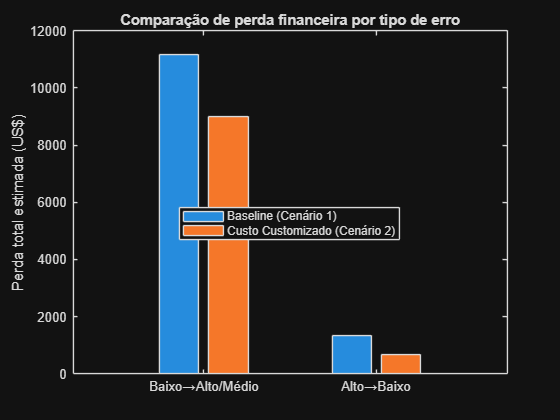

function [perdaTotalFare, perdaMediaFare, perdaMediaFarePorMilha, fares] = ...
    calcularPerdaAltoSubestimado(TaxiTestTbl, yTrueVec, yPredVec)

idxErro = (yTrueVec == "Alto") & (yPredVec == "Baixo");
linhasErro = find(idxErro);

fares       = TaxiTestTbl.AvgFare(linhasErro);
distancias  = TaxiTestTbl.AvgDistance(linhasErro);
farePorMilha = fares ./ distancias;

valido = ~isnan(fares) & ~isnan(farePorMilha) & ~isinf(farePorMilha);

perdaTotalFare         = sum(fares(valido));
perdaMediaFare         = mean(fares(valido));
perdaMediaFarePorMilha = mean(farePorMilha(valido));
fares = fares(valido);
end

%% Aplicar aos dois modelos
[perdaTotalBaseline_A, perdaMediaBaseline_A, farePorMilhaBaseline_A, ~] = ...


--- Perda total combinada ---


    calcularPerdaAltoSubestimado(TaxiTest, yTest, yPredBaseline);

Baseline:  $12512.35


Cenário 2: $9654.94


[perdaTotalCenario2_A, perdaMediaCenario2_A, farePorMilhaCenario2_A, ~] = ...
    calcularPerdaAltoSubestimado(TaxiTest, yTest, yPredCenario2);

fprintf('\n--- Perda por Alto mal classificado como Baixo ---\n');

Diferença: $2857.41 (22.8% menor no Cenário 2)


fprintf('Baseline:  Perda total = $%.2f | Tarifa média perdida = $%.2f | Tarifa/milha média = $%.2f\n', ...
    perdaTotalBaseline_A, perdaMediaBaseline_A, farePorMilhaBaseline_A);
fprintf('Cenário 2: Perda total = $%.2f | Tarifa média perdida = $%.2f | Tarifa/milha média = $%.2f\n', ...
    perdaTotalCenario2_A, perdaMediaCenario2_A, farePorMilhaCenario2_A);

#### Visualização: perda total por tipo de erro, por modelo

figure
categoriasErro = categorical({'Baixo→Alto/Médio','Alto→Baixo'});
categoriasErro = reordercats(categoriasErro, {'Baixo→Alto/Médio','Alto→Baixo'});

perdasBaseline = [perdaTotalBaseline_B, perdaTotalBaseline_A];
perdasCenario2 = [perdaTotalCenario2_B, perdaTotalCenario2_A];

bar(categoriasErro, [perdasBaseline; perdasCenario2]')
legend({'Baseline (Cenário 1)','Custo Customizado (Cenário 2)'}, 'Location', 'best')
ylabel('Perda total estimada (US$)')
title('Comparação de perda financeira por tipo de erro')

O Cenário 2 reduz a perda financeira total estimada em 22,8%, ou US$ 2.857,41, em relação ao Cenário 1, ao custo de uma redução de apenas 0,38 ponto percentual na acurácia geral. Esse *trade-off* é totalmente justificado dado o alinhamento direto do Cenário 2 com a estratégia de despacho. Recomendação: adotar o modelo do Cenário 2.

%% Perda total combinada (visão geral de qual modelo "perde menos dinheiro")
perdaTotalGeralBaseline = perdaTotalBaseline_B + perdaTotalBaseline_A;
perdaTotalGeralCenario2 = perdaTotalCenario2_B + perdaTotalCenario2_A;

fprintf('\n--- Perda total combinada ---\n');
fprintf('Baseline:  $%.2f\n', perdaTotalGeralBaseline);
fprintf('Cenário 2: $%.2f\n', perdaTotalGeralCenario2);
fprintf('Diferença: $%.2f (%.1f%% %s)\n', ...
    abs(perdaTotalGeralBaseline - perdaTotalGeralCenario2), ...
    abs(perdaTotalGeralBaseline - perdaTotalGeralCenario2) / perdaTotalGeralBaseline * 100, ...
    ternary(perdaTotalGeralCenario2 < perdaTotalGeralBaseline, 'menor no Cenário 2', 'menor no Baseline'));
function out = ternary(cond, a, b)
if cond, out = a; else, out = b; end
end

Com os dois modelos treinados, avaliados e comparados quanto ao impacto financeiro estimado, o projeto reúne evidências suficientes para uma recomendação final, sintetizada a seguir.

# 5. Conclusões do Projeto

Retomando a pergunta que orientou este projeto (é mais vantajoso maximizar a acurácia geral ou alinhar o modelo aos custos dos erros mais relevantes para a operação?), os resultados obtidos permitem uma resposta objetiva, detalhada nos tópicos abaixo.

**1. Transformação dos dados em informação para tomada de decisão**

O projeto transformou dados históricos de viagens de táxi em uma classificação de demanda por região e hora, permitindo representar a demanda em três níveis: **Baixa, Média e Alta**. Dessa forma, informações originalmente distribuídas em milhões de registros individuais foram convertidas em uma estrutura mais adequada para analisar e apoiar decisões de despacho.

**2. A acurácia geral não é suficiente para avaliar a melhor solução**

A análise mostrou que a demanda não deve ser avaliada exclusivamente pela acurácia geral do modelo. Em um contexto operacional, diferentes tipos de erro podem gerar consequências diferentes para o negócio. Portanto, um modelo com maior número total de acertos não é necessariamente aquele que produz a melhor decisão operacional.

**3. O Cenário 1 estabeleceu uma referência de desempenho**

O Cenário 1 foi desenvolvido como modelo baseline, com foco na maximização da acurácia geral da classificação. A árvore de decisão utilizada nesse cenário apresentou **71,71% de acurácia no conjunto de teste**, servindo como referência para avaliar os impactos da adoção de uma estratégia orientada pelos custos dos erros.

**4. O Cenário 2 incorporou as prioridades da estratégia de despacho**

O Cenário 2 foi desenvolvido considerando que determinados erros possuem maior impacto para a operação. A estratégia prioriza regiões de maior demanda e busca evitar o direcionamento ou a permanência de táxis em regiões de Baixa demanda. Para representar essas prioridades, o modelo atribuiu custos diferentes aos possíveis erros de classificação.

**5. Uma pequena redução na acurácia pode gerar uma decisão mais adequada ao negócio**

A abordagem orientada ao custo apresentou uma pequena redução na acurácia geral em relação ao modelo baseline. Entretanto, essa redução foi acompanhada por um melhor alinhamento com os objetivos operacionais definidos para o problema, priorizando a redução dos erros considerados mais prejudiciais à estratégia de despacho.

**6. O Cenário 2 apresentou menor perda financeira estimada**

Ao traduzir os principais erros de classificação em impacto financeiro estimado, o Cenário 2 apresentou uma redução de **22,8% na perda financeira total estimada**, equivalente a **US$ 2.857,41**, em comparação com o Cenário 1. Esse resultado foi obtido com uma redução de apenas **0,38 ponto percentual na acurácia geral**.

**7. A abordagem recomendada é o Cenário 2**

Considerando conjuntamente o desempenho preditivo, a estratégia operacional e o impacto financeiro estimado, o **Cenário 2 é a abordagem recomendada**. Embora não maximize exclusivamente a acurácia geral, ele apresenta maior aderência às prioridades do negócio e menor perda financeira estimada dentro das premissas estabelecidas no projeto.

## Recomendação Final

Recomenda-se a adoção do modelo desenvolvido no **Cenário 2** como abordagem preferencial para apoiar a estratégia de despacho de táxis.

O principal resultado do projeto demonstra que **o melhor modelo para um problema de negócio não é necessariamente aquele que apresenta a maior acurácia geral, mas aquele que toma decisões mais alinhadas aos impactos e prioridades da operação**.

Neste caso, a pequena redução observada na acurácia geral é compensada pela redução estimada das perdas associadas aos erros mais relevantes para a estratégia de despacho. Portanto, o Cenário 2 apresenta o melhor equilíbrio entre desempenho preditivo e impacto operacional e financeiro estimado.

**Importante:** os valores financeiros apresentados representam estimativas calculadas com base nos dados históricos e nas premissas definidas ao longo do projeto. Dessa forma, os resultados devem ser interpretados como evidências para apoiar a tomada de decisão, e não como uma garantia de economia financeira futura.